Drawing the line

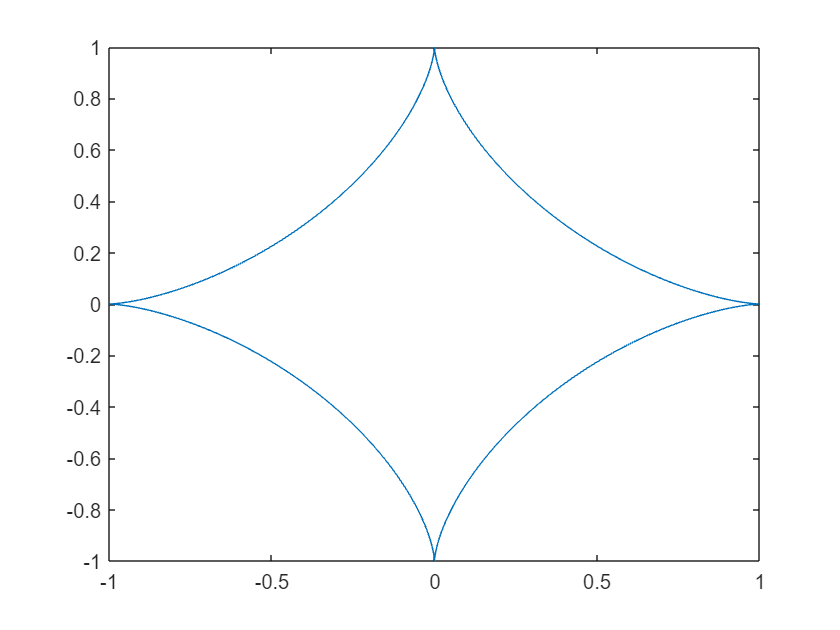

T = 0:0.01:2*pi;
X = cos(T).^3;
Y = sin(T).^3;
plot(X,Y)

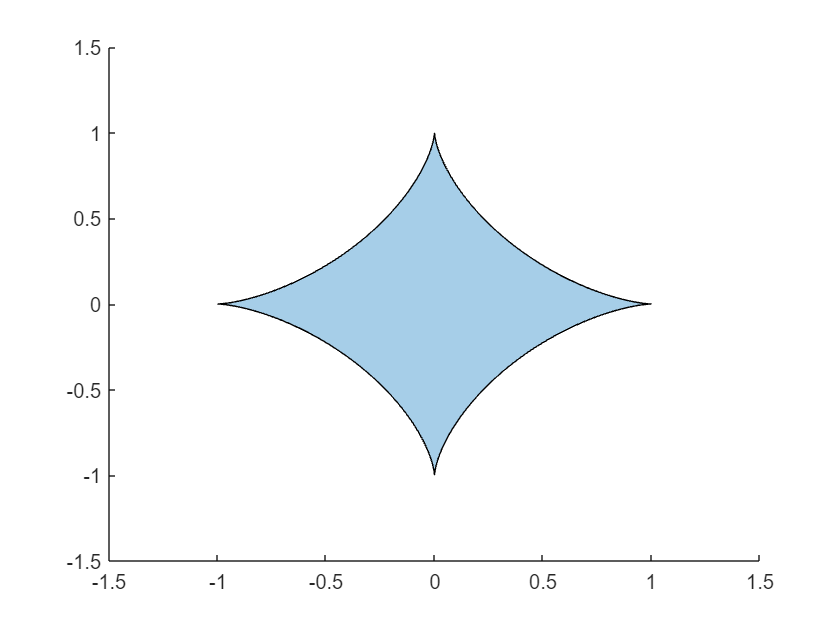

Asteroid = polyshape([X',Y']);
plot(Asteroid)

Calculate perimeter

perimeter(Asteroid)

ans = 5.9999

the perimeter is approxiately 6

syms t
expr = sqrt(diff(sin(t)^3)^2+diff(cos(t)^3)^2)

$$expr = 3\,\sqrt{{\cos\left(t\right)}^{4}\,{\sin\left(t\right)}^{2}+{\cos\left(t\right)}^{2}\,{\sin\left(t\right)}^{4}}$$

4*int(expr,0,pi/2)

$$ans = 6$$

the accurate result is 6 as expected.

For given t0 in [0,pi/2], the tangent line at the point is sin(t)cos(t) = xsin(t)+ycos(t), therefore its length is 1

Since it has fixed length, a stick can slide along this path without streaching.

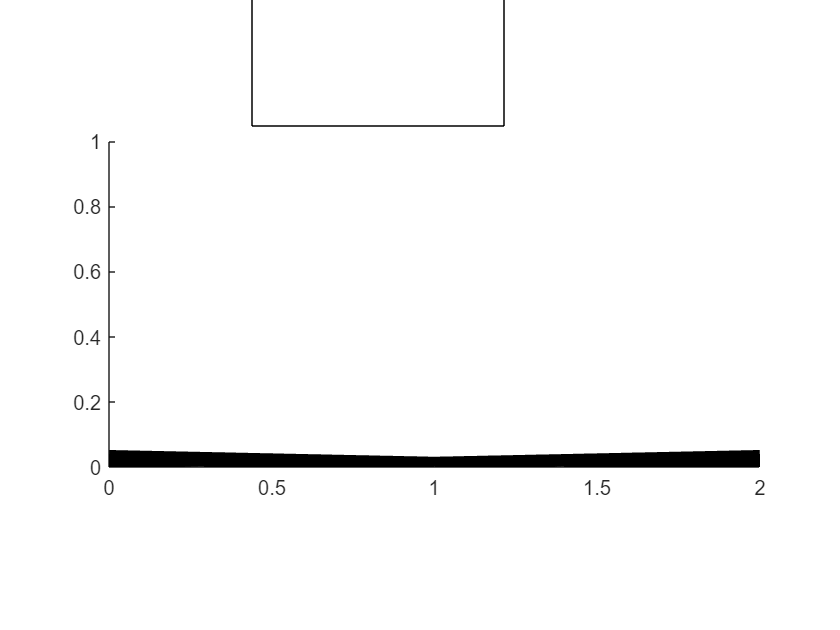

for t = 0:0.05:pi/2
    clf
    %plot(Asteroid)
    hold on
    plot([0,sin(t)],[cos(t),0],"LineWidth",10,"Color",'k')
    plot([0,-sin(t)]+2,[cos(t),0],"LineWidth",10,"Color",'k')
    xlim([0 2])
    ylim([0 1])
    pbaspect([2 1 1])
    text()
    drawnow
end